clear all;
clc;

%% 1Arc example 
% Load DICOM
path = cd;
DICOM_path = [path,'/example/test_case/0026_VMATQATEST.dcm'];
BLD_type = 'agility';
VMAT_PLN_INFO = VMAT_PLAN(DICOM_path);

Total MU:729.763367 
Total control points: 154 
Fractions:28 
Target prescription dose(Gy):61.600000 
This is 1 th control point 
This is 2 th control point 
This is 3 th control point 
This is 4 th control point 
This is 5 th control point 
This is 6 th control point 
This is 7 th control point 
This is 8 th control point 
This is 9 th control point 
This is 10 th control point 
This is 11 th control point 
This is 12 th control point 
This is 13 th control point 
This is 14 th control point 
This is 15 th control point 
This is 16 th control point 
This is 17 th control point 
This is 18 th control point 
This is 19 th control point 
This is 20 th control point 
This is 21 th control point 
This is 22 th control point 
This is 23 th control point 
This is 24 th control point 
This is 25 th control point 
This is 26 th control point 
This is 27 th control point 
This is 28 th control point 
This is 29 th control point 
This is 30 th control point 
This is 31 th control point 
This is 


% calculate Modulation Index of leaf speed VMAT_PLN_INFO.ALS,VMAT_PLN_INFO.SLS
% VMAT_PLN_INFO = MI_leafspeed_TEST(VMAT_PLN_INFO);
VMAT_PLN_INFO = MI_leafspeed(VMAT_PLN_INFO);

% calculate Modulation Index of leaf acceleration
VMAT_PLN_INFO = MI_leafacceleration(VMAT_PLN_INFO);

% calculate Total Modulation Index including gantry acceleration, DR variation, MLC speed, MLC acceleration
% VMAT_PLN_INFO.DOSERATE,VMAT_PLN_INFO.GantrySpeed,VMAT_PLN_INFO.ADR,VMAT_PLN_INFO.SDR
VMAT_PLN_INFO = MI_TotalModulation(VMAT_PLN_INFO);

% calculate aperture perimeter (VMAT_PLN_INFO.AP)
VMAT_PLN_INFO = Aperture_Perimeter(VMAT_PLN_INFO,BLD_type);

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 1th control point is 49.990000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 3th control point is 70.060000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 4th control point is 69.600000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 5th control point is 83.730000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 6th control point is 90.540000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 9th control point is 130.140000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 11th control point is 112.230000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 12th control point is 110.280000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 13th control point is 91.840000 cmrem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
perimeter for 17th control point is 69.580000 cmrem(start_point,1) ~= 0 && rem(en


% calculate aperture area (VMAT_PLN_INFO.AA)
VMAT_PLN_INFO = Aperture_Area(VMAT_PLN_INFO,BLD_type);

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   20.6700

    53

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   58.5833

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   68.5489

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   76.3540

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   81.3186

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   64.5926

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
  111.3040

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
  104.3590

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   87.5270

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   56.1760

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   86.9853

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   93.2228

    63

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   89.0620

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   81.2540

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   69.7613

rem(start_point,1) ~= 0 && rem(end_point,1) ~= 0
   37.3964

rem(star

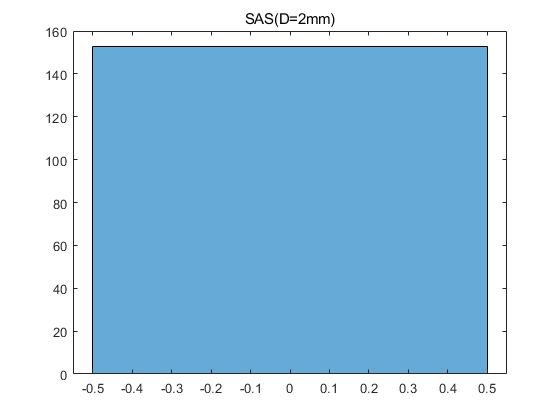

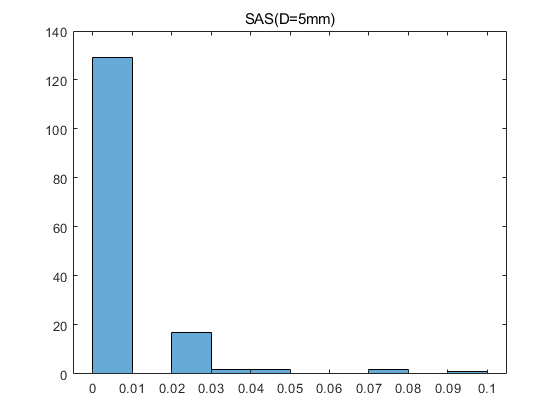

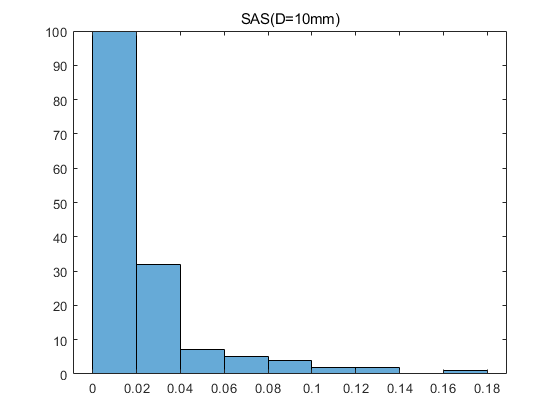

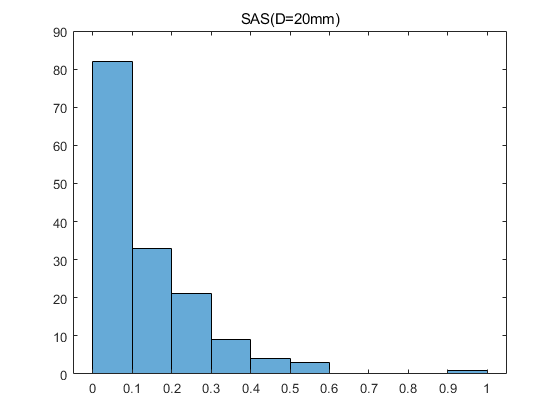


% calculate mean field area (VMAT_PLN_INFO.MFA)
VMAT_PLN_INFO = Mean_Field_Area(VMAT_PLN_INFO);

% calculate small aperture score (SAS) 5mm, 10mm, 20mm 
VMAT_PLN_INFO = Small_Aperture_Score(VMAT_PLN_INFO,BLD_type);


% calculate mean asymmetry distance (VMAT_PLN_INFO.MAD)
VMAT_PLN_INFO = Mean_Asymmetry_Distance(VMAT_PLN_INFO,BLD_type);

% calculate leaf sequence variability (VMAT_PLN_INFO.LSV)
VMAT_PLN_INFO = Leaf_Sequence_Variability(VMAT_PLN_INFO,BLD_type);

% calculate aperture area variability (VMAT_PLN_INFO.AAV)
VMAT_PLN_INFO = Aperture_Area_Variability(VMAT_PLN_INFO,BLD_type);

% calculate Modulation complex score (VMAT_PLN_INFO.MCS)
VMAT_PLN_INFO = Modulation_Complexity_Score(VMAT_PLN_INFO);

% calculate plan related metrics including PA,PI,PM,PMU
VMAT_PLN_INFO = PLAN_PI_PA_PM_PMU(VMAT_PLN_INFO,BLD_type);

% calculate plan edge metric 
VMAT_PLN_INFO = Edge_Metric(VMAT_PLN_INFO,BLD_type);

% calculate Average Leaf Travel (VMAT_PLN_INFO.LT)
VMAT_PLN_INFO = Leaf_Travel(VMAT_PLN_INFO,BLD_type);

% calculate Average Leaf Travel (VMAT_PLN_INFO.LT)
VMAT_PLN_INFO = LTMCS(VMAT_PLN_INFO);

% calculate Modulation Index proposed by Xinglei and Li ruijiang (VMAT_PLN_INFO.MI_XING) [undo]
VMAT_PLN_INFO = MI_SPORT(VMAT_PLN_INFO)

% calculate Converted Aperture metric (VMAT_PLN_INFO.CAM) [undo]
VMAT_PLN_INFO = Converted_Aperture(VMAT_PLN_INFO)

VMAT_PLN_INFO = 包含以下字段的 struct :
                       Total_MU: 729.7634
                      Total_CPs: 154
                             FX: 28
                            TPD: 61.6000
                        CP_info: {154×4 cell}
                  MLC_speed_std: [160×1 double]
                        MI_S_02: 15.5922
                        MI_S_05: 31.5583
                         MI_S_1: 50.4775
                         MI_S_2: 72.5090
                  MLC_speed_mat: [160×153 double]
               CP_time_interval: [153×1 double]
                            ALS: 10.2717
                            SLS: 17.6762
           MLC_acceleration_mat: [160×152 double]
           MLC_acceleration_std: [160×1 double]
               MI_Accelerate_02: 17.2112
               MI_Accelerate_05: 36.1777
                MI_Accelerate_1: 58.6651
                MI_Accelerate_2: 82.3327
                            ALA: 21.6535
                            SLA: 22.3339
          MI_TotalModulation_


% calculate Edge Area metric (VMAT_PLN_INFO.EAM) [undo]
VMAT_PLN_INFO = Edge_Area(VMAT_PLN_INFO)

未定义与 'struct' 类型的输入参数相对应的函数 'Edge_Area'。


% calculate Circumference/area (VMAT_PLN_INFO.C/A) [undo]
VMAT_PLN_INFO = Circumference_Area(VMAT_PLN_INFO)

